filename = "C:\Users\dfpsi\sciebo\ProjektSeminar\dataset\subject1\stage1\imgB1.mat";
load(filename)

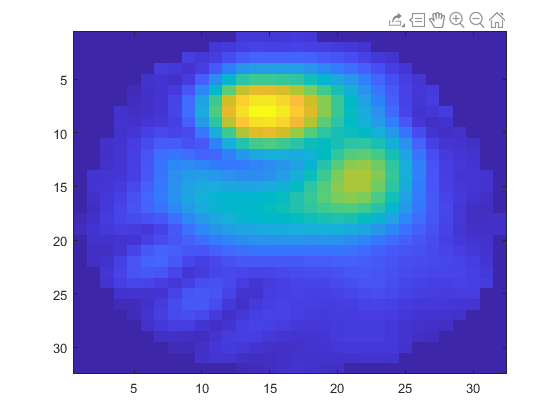

% Choose heart pixel
figure; imagesc(std(imgB1,[],3)); [Y,X] = getpts;

signal = squeeze(imgB1(round(X),round(Y),:));

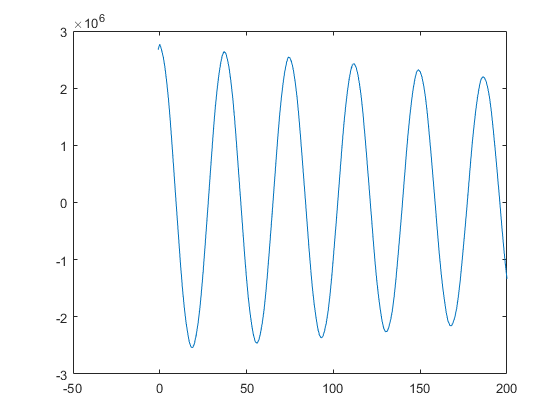

% Calculate least correlation delay
maxLag = 200;
[r,lags] = xcorr(signal,signal,maxLag); r = r(200:end); lags = lags(200:end);
figure; plot(lags,r)

delay = 9;
x1 = signal;
x2 = circshift(signal,delay);
x3 = circshift(signal,2 * delay);

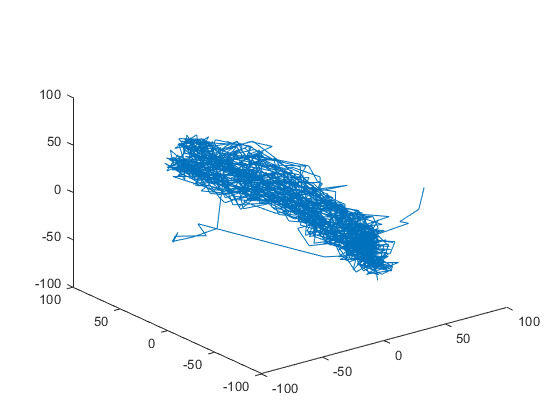

% Plot phase domain
figure; plot3(x1,x2,x3)

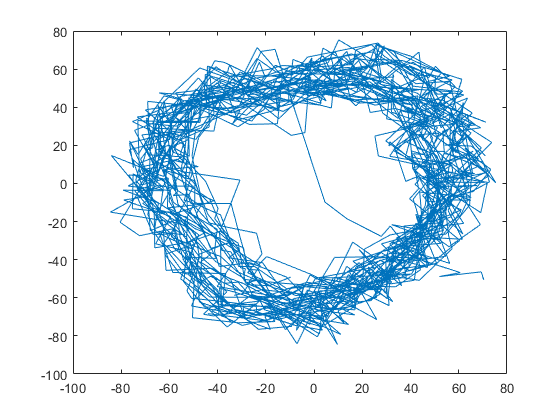

figure; plot(x1,x2)

% Improve sampling frequency through spline interpolation
s = spline(1:length(signal),signal,linspace(1,length(signal),7500));

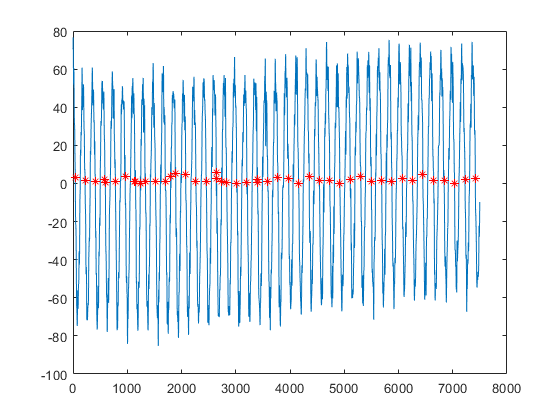

% Get CRS waveform
zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);
locs = zci(s); locs = locs(1:2:end);

figure; plot(s); hold on; plot(locs,s(locs),'r*')

avgBeat = zeros(1,300);
count = 0;
for l = 1:2:length(locs)
    wave = s(locs(l):locs(l+1));
    wave = spline(1:length(wave),wave,linspace(1,length(wave),300));
    avgBeat = avgBeat + wave;
    count = count + 1;
end

Index exceeds the number of array elements (47).

avgBeat = avgBeat / count;

figure; plot(avgBeat)

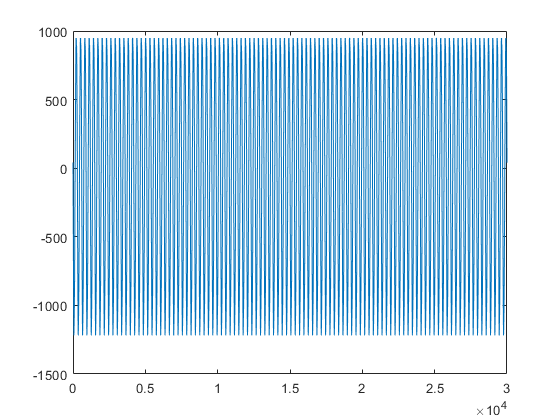

% Repat average waveform
artSignal = repmat(avgBeat,1,100);
figure; plot(artSignal)

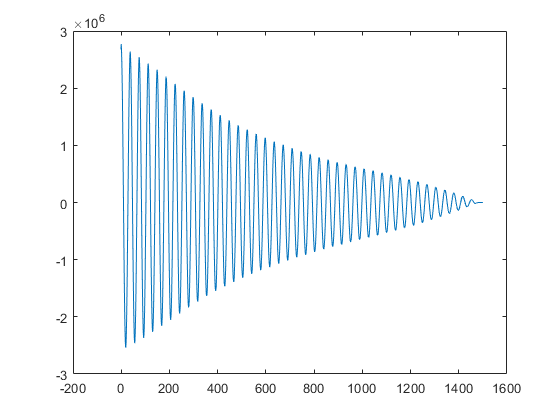

% Calculate least correlation delay
maxLag = 1500;
[r,lags] = xcorr(signal,signal,maxLag); r = r(maxLag:end); lags = lags(maxLag:end);
figure; plot(lags,r)

delay = 9;
x1 = artSignal;
x2 = circshift(artSignal,delay);
x3 = circshift(artSignal,2 * delay);

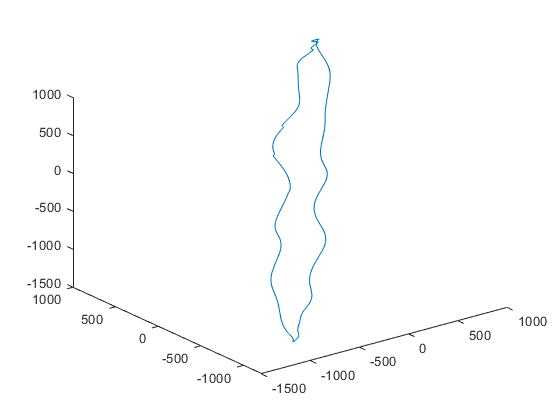

% Plot phase domain
figure; plot3(x1,x2,x3)

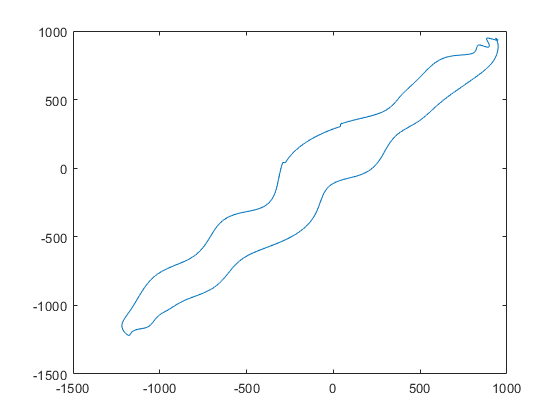

figure; plot(x1,x2)

filename = "C:\Users\dfpsi\sciebo\ProjektSeminar\dataset\subject1\stage1\imgV2.mat";
load(filename)
signal = squeeze(imgV2(round(X),round(Y),:));

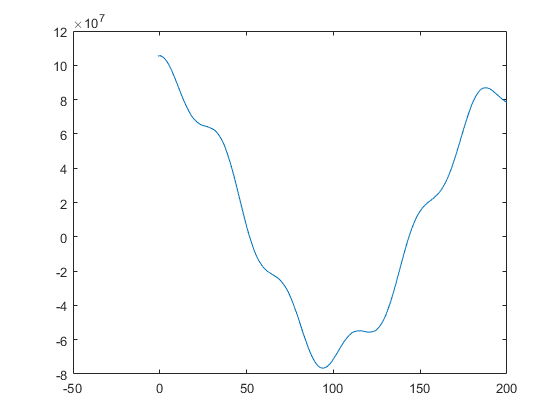

% Calculate least correlation delay
maxLag = 200;
[r,lags] = xcorr(signal,signal,maxLag); r = r(200:end); lags = lags(200:end);
figure; plot(lags,r)

delay = 50;
signalSeg = signal(1000:2000);
x1 = signalSeg;
x2 = circshift(signalSeg,delay);
x3 = circshift(signalSeg,2 * delay);

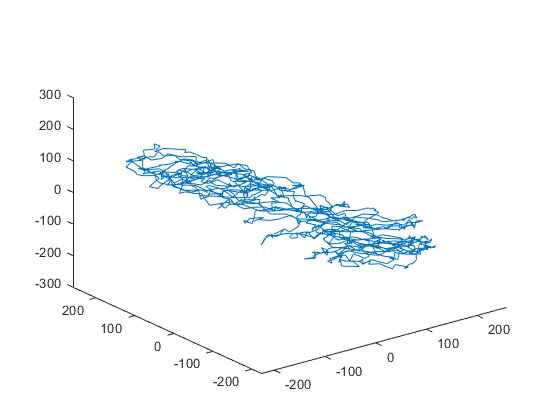

% Plot phase domain
figure; plot3(x1,x2,x3)

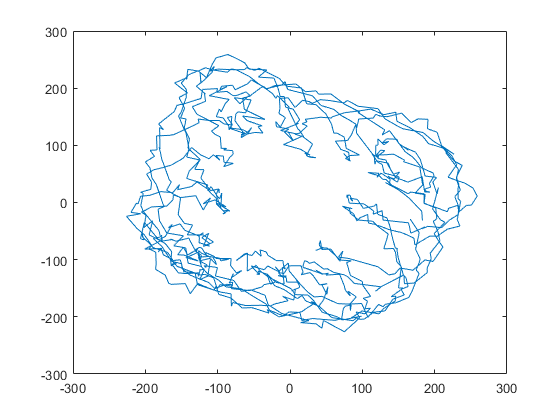

% X = WS;
% [Xn+1] = A*Xn; Atilde = Xn/Xn+1; [U,S,V] = svd(X);
% dt = a * x; x(t) = x(0)*exp(-a*t);
% A = P*D*Pinv;
% Px = u;
% u(t) = u(0)*exp(-D*t);
% u(t) = x(0) * P * exp(-D*t);
% u1(t) = x1(0) * P(1) * exp(-D1*t);
% deltat

figure; plot(x1,x2)